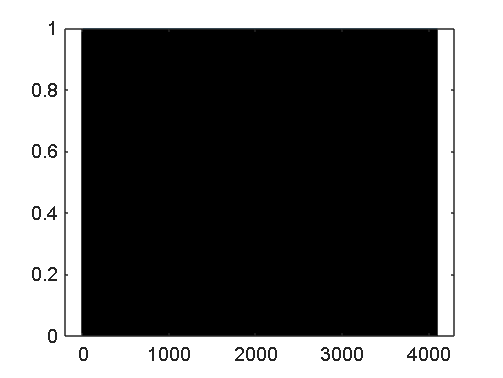

clear all;
close all;
clc
N = 12; %resolution
Vcm = 0.9; 

sampling_points=4095;
data=csvread(['LFSR12.csv'],2,1);
Digital_code = zeros(sampling_points,N);
%Convert analog signal to digital code
for i= 1:sampling_points
    for j = 1:N
        if data(i,j)>Vcm
            Digital_code(i,j)=1;
        end
    end
end

Daq = zeros(sampling_points,1);
for k=1:sampling_points
    for i=1:N
        Daq(k) = Daq(k) + (2^(N-i)).*Digital_code(k,i);
    end
end

histogram(Daq, 4095);